**Guião 2**

- Determine o período, a frequência e o valor máximo (valor de pico) de cada um dos seguintes sinais periódicos. Verifique visualmente no MATLAB.

a) 𝑥(𝑡) = 2 sin(4𝜋𝑡) 

Ta=0.001; %passo
T=1/2;
t=0:Ta:3*T-Ta; %mostra 3 períodos e retira o último salto de Ta no fim
x=2*sin(2*pi*2*t);
plot(t,x)
title("a)")
grid on


pa = potencia(x,Ta,T) %potência A

pa = 2

f= 1/T =2

b) 𝑦(𝑡) = sin(10𝜋𝑡 + 𝜋/2)

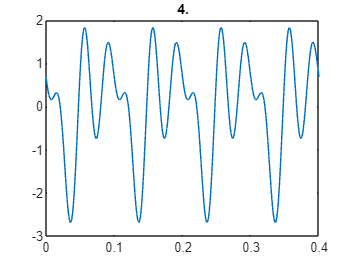

Ta=0.001;
T=1/5;
t=0:Ta:3*T-Ta;
x=sin(10*pi*t+pi/2);
plot(t,x)
title("b)")
grid on


pb = potencia(x,Ta,T)

pb = 0.5000

c) 𝑝(𝑡) = sin(20𝜋𝑡 + 70𝜋/180) + sin(20𝜋𝑡 + 200𝜋/180)

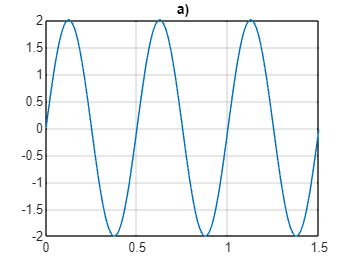

Ta=0.001;
T=1/10;
t=0:Ta:3*T-Ta;
x=sin(20*pi*t+70*pi/180)+sin(20*pi*t+200*pi/180);
plot(t,x)
title("c)")
grid on


pc = potencia(x,Ta,T)

pc = 0.3572

d) 𝑧(𝑡) = sin(6𝜋𝑡) + sin(8𝜋𝑡)

Ta=0.001;
%% sin(6*pi*t)
T1 = (2*pi)/(6*pi);
%% sin(8*pi*t)
T2 = (2*pi)/(8*pi);
%% Para calcular o T da função z, é necessário encontrar o LCM
%% entre T1 e T2, neste caso entre 1/3 e 1/4. LCM(1/3,1/4) é 1.
T = 1

T = 1

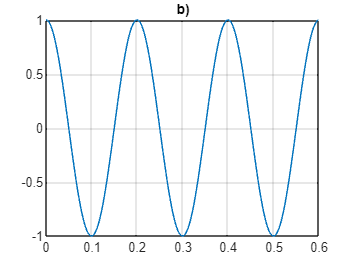

t=0:Ta:3*T-Ta;
x=sin(6*pi*t)+sin(8*pi*t);
plot(t,x)
title("d)")
grid on


pd = potencia(x,Ta,T)

pd = 1

e) 𝑤(𝑡) = sin(6𝜋𝑡) + sin(8𝜋𝑡 + 0.1)

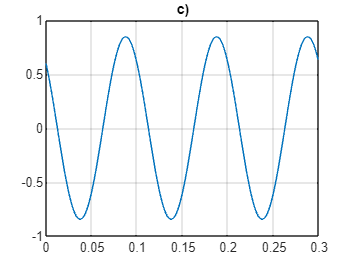

Ta=0.001;
mdc = gcd(3,4);
T=1/mdc; %inverso do máximo divisor comum entre as frequências [3, 4] ;
t=0:Ta:3*T-Ta;
x=sin(6*pi*t)+sin(8*pi*t+0.1);
plot(t,x)
title("e)")
grid on


pe = potencia(x,Ta,T)

pe = 1.0000

f) 𝑞(𝑡) = sin(6𝜋𝑡) + sin(7𝜋𝑡) + sin(8𝜋𝑡)

Ta=0.001;
mdc = gcd(6,7)

mdc = 1

mdc2 = gcd(mdc,8)

mdc2 = 1

T=1/mdc2 %inverso do máximo divisor comum entre as frequências [3, 3.5, 4] -> mdc=0.5;

T = 1

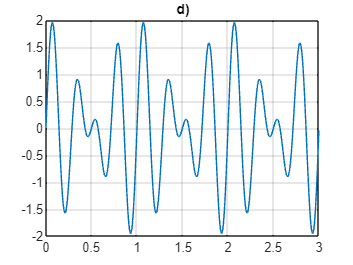

t=0:Ta:3*T-Ta;
x=sin(6*pi*t)+sin(7*pi*t)+sin(8*pi*t);
plot(t,x)
title("f)")
grid on


pf = potencia(x,Ta,T)

pf = 1.5000

2. Obtenha a relação que determina o período de um sinal genérico descrito por: 𝑥(𝑡) = ∑𝐴𝑛 sin(2𝜋𝑓𝑛𝑡 + 𝜙𝑛 ) 𝑁 𝑛=1 .

% A relação que determina o período de um sinal genérico é o inverso do máximo divisor comum entre as frequências dos sinais. 

3.   Determine a potência associada a cada um dos sinais representados na alínea 1.  

- Calculado no exercício 1    

- A função da potência encontra-se no final do script.

4. 

Ta = 0.001;
N = 3;
A = [1,1,1];
f = [10,20,30];

mdc1 = gcd(f(1),f(2));
f1 = gcd(mdc1,f(3));

f1 = 10

T = 1/f1;

t = 0:Ta:4*T;

psi = rand(1,3)*2*pi-pi;

soma = 0;
for i = 1:N
    soma = soma + A(i)*sin(2*pi*f(i)*t+psi(i));
end

plot(t,soma);
title("4.")


p = potencia(soma,Ta,T)

p = 1.5000

Definição da função potência:

function P = potencia(x,Ta,T)
    maxIndex = T/Ta;
    x = x(:,1:maxIndex);
    P = x*x'/maxIndex;
end